# Swing by Venus - Numerik Abschlussprojekt

Urs Müller, Joachim Spitaler, Leonie Graf

Leonie is cool!

**1) Sonnensystem**

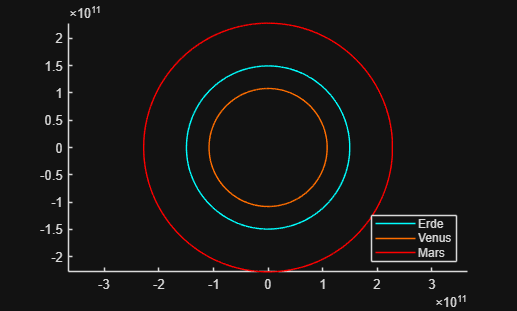

clear all, close all, clc, clf  

tspan = linspace(0,700,100000);     %Zeitspanne für Zeichnen der Planetenbahnen

%Grober Mars-Startwinkel, durch vorherige Ausführungen bestimmt, wird
%später im Programm präzisiert
%Für Anfang des Programms relativ irrelevant, da Mars sehr klein ist!
phi0M = -1.71;                      

%Umlaufbahnen der Planeten berechnen
Earth = posEarth(tspan);
Venus = posVenus(tspan);
Mars = posMars(tspan, phi0M);

figure;
hold on;
plot(Earth(:,1), Earth(:,2),"c");
plot(Venus(:,1), Venus(:,2),"Color","#FF6E00");
plot(Mars(:,1), Mars(:,2),"r");
axis equal;
legend({"Erde", "Venus", "Mars"}, 'Location', 'southeast')

**2) Gravitationsfeld **

%Startposition der Venus abgreifen
rV = posVenus(0)';
%Von 100km bis 1 Milliarde km 
dmin = 1e5;
dmax = 1e12;

%Anonyme Funktion deklarieren, Distanz kann variiert werden
f = @(d) venus_ratio(d,phi0M,rV);

%Nullstellensuche über fzero
dsolve = fzero(f,[dmin;dmax]); 
fprintf("Abstand zu Venus bei 0.01 der Gravitation = %.f km",dsolve/1000)

Abstand zu Venus bei 0.01 der Gravitation = 1693196 km

**3) Bahnkurve einer Sonde**

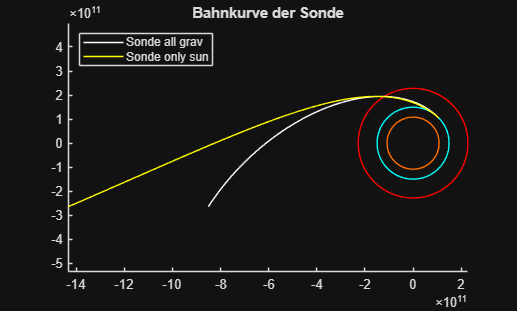

v0 = 15 * 10^3 * 86400;         %Startgeschwindigkeit, Meter/Tage
angle = 0;                      %Startwinkel für einen tangentialen Start zur Erdlaufbahn
options = odeset("AbsTol",1e-8, "RelTol",1e-6, "MaxStep", 0.01);

%Funktion addiert Erdgeschwindigkeit, richtet nach Winkel aus
[pos, v0_vec] = v0_calc(v0, angle);
%Flugbahn der Sonde mit allen Gravitationen
[~, y] = ode113(@(t,y) grav_calc(t,y,phi0M), tspan, [pos'; v0_vec], options);
sonde_all_grav = plot(y(:,1), y(:,2), "w-"); 
hold on;

%Flugbahn der Sonde mit ausschließlich der Sonnengravitation
[t_sun, y_sun] = ode45(@grav_sun, tspan, [pos'; v0_vec], options);
sonde_only_sun = plot(y_sun(:,1), y(:,2),"y-");

legend([sonde_all_grav,sonde_only_sun],{"Sonde all grav","Sonde only sun"}, 'Location','northwest')
title("Bahnkurve der Sonde")

**4) Trajektorie**

v0 = 13.333 * 10^3 * 86400;     %Startgeschwindigkeit, Meter/Tage
target_dist = 12300 * 10^3;     %Gewünschte Venus-Distanz in Metern

%Eingrenzung der Startwerte
test_angles = linspace(0, -1.8, 36);    %Testwinkel für grobe Eingrenzung
test_diffs = zeros(size(test_angles));  %Ergebnisvektor erstellen

%Nur wenige Iterationen, wenig Rechenaufwand
for i = 1:length(test_diffs)            
    test_diffs(i) = flybyV_dist(test_angles(i), v0, phi0M, target_dist);
end

%Minimum aus Ergebnisvektor auslesen, speichern
[~, idx] = min(test_diffs);

%Anonyme Funktion definieren, Winkel wird variiert
objective_min = @(a) (flybyV_dist(a, v0, phi0M, target_dist))^2;

%Startwinkel von oben verwenden
start_angle = test_angles(idx); %Startwert

%fminsearch, minimale Differenz zu gewünschter Distanz bestimmen
best_angle = fminsearch(objective_min, start_angle);

%Ergebnisse mit bestem Startwinkel auswerten
[~, min_dist, flyby_t] = flybyV_dist(best_angle, v0, phi0M, target_dist);

fprintf("Bestimmung optimaler Sonden-Abschusswinkel:");

Bestimmung optimaler Sonden-Abschusswinkel:

fprintf("---------------------------------------") 

---------------------------------------

fprintf("Ergebnis Startwinkeleingrenzung: %.3f rad\n", start_angle);

Ergebnis Startwinkeleingrenzung: -1.594 rad


fprintf("Optimaler Abschuss-Winkel: %.6f rad\n", best_angle);    %Optimalen Abschusswinkel ausgeben

Optimaler Abschuss-Winkel: -1.611721 rad


fprintf("Abstand zu Venus bei Flyby: %.2fkm\n", min_dist/1000);    %Distanz ausgeben

Abstand zu Venus bei Flyby: 12300.00km


fprintf("Zeitpunkt Flyby Venus: %.2f Tage\n", flyby_t)

Zeitpunkt Flyby Venus: 214.72 Tage


fprintf("---------------------------------------");             %Visuelle Abgrenzung Output

---------------------------------------

**5) Mars **

test_phis = linspace(0.3, 1.5, 60);             %Testwinkel für grobe Eingrenzung
test_diffs_phi = zeros(size(test_angles));      %Ergebnisvektor erstellen

for i = 1:length(test_angles)
    test_diffs_phi(i) = flybyM_dist(test_phis(i), best_angle, v0);
end

%Minimum aus Ergebnisvektor auslesen, speichern
[~, idx] = min(test_diffs_phi);

%Mars - Startwinkel von oben verwenden
start_phi = test_angles(idx); 

%Anonyme Funktion definieren, Startwinkel Mars wird variiert
objective_min = @(phi) (flybyM_dist(phi, best_angle, v0))^2;

%Minimale Differenz zu gewünschtem Abstand mit fminsearch bestimmen
best_phi = fminsearch(objective_min, start_phi);

%Ergebnisse von Flug mit bestem Mars-Start auswerten
[~, min_dist, mars_hit_t] = flybyM_dist(best_phi, best_angle, v0);

fprintf("Bestimmung optimaler Mars-Startwinkel:");

Bestimmung optimaler Mars-Startwinkel:

fprintf("---------------------------------------");

---------------------------------------

fprintf("Ergebnis Startwinkeleingrenzung Mars: %.3f rad\n", start_phi);

Ergebnis Startwinkeleingrenzung Mars: -1.646 rad


fprintf("Optimaler Startwinkel Mars: %.2f rad\n", best_phi);

Optimaler Startwinkel Mars: -1.66 rad


fprintf("Minimaler Abstand: %.0f km\n", min_dist/1000);

Minimaler Abstand: 20000 km


fprintf("Flyby-Zeitpunkt Mars: %.2f Tage\n", mars_hit_t);

Flyby-Zeitpunkt Mars: 385.15 Tage


fprintf("---------------------------------------");

---------------------------------------

**Ergebnisse darstellen**

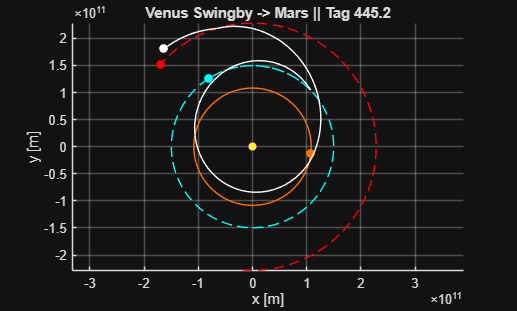

% Simulation bis zum Mars-Treffzeitpunkt
tspan = [0 (mars_hit_t+60)];

%Startgeschwindigkeit berechnen
[pos0, v0_vec] = v0_calc(v0, best_angle);
y0 = [pos0(:); v0_vec(:)];

options = odeset("AbsTol",1e-10,"RelTol",1e-8);

%"Optimierten" Flug durchführen
[t, y] = ode113(@(t,y) grav_calc(t,y,best_phi), tspan, y0, options);

ref_plot = 1000;                               %Nummer Zeitschritte der Animation
t_plot = linspace(t(1), t(end), ref_plot);     %Zeit-Vektor für Animation erstellen

rS = y(:,1:2);                              %Position Sonde

%Pos-Daten auf t_plot intepolieren, gleichmäßige Darstellung
%Sonst zu viele Schritte bei steiferen Stellen
rS_plot = interp1(t, rS, t_plot);           
 
%Planeten-Positionen berechnen
rE = posEarth(t_plot);
rV = posVenus(t_plot);
rM = posMars(t_plot, best_phi);

rV_calc = posVenus(t);
%Für Distanzberechnung, ungenau nach Interpolation

%Kreibahnen Planeten
tt = linspace(0, max(t), 500);
bE = posEarth(tt);
bV = posVenus(tt);
bM = posMars(tt, best_phi);

figure
hold on
axis equal
grid on

%Bahnen (gestrichelt)
plot(bE(:,1), bE(:,2), 'c--')
plot(bV(:,1), bV(:,2), 'Color','#FF6E00')
plot(bM(:,1), bM(:,2), 'r--')
plot(0,0,"Marker","o", "MarkerFaceColor","y") %Sonne im Mittelpunkt

%Animierte Objekte (Startwerte)
hE = plot(rE(1,1), rE(1,2), "co", "MarkerFaceColor","c");
hV = plot(rV(1,1), rV(1,2), "Color", "#FF6E00", "Marker","o", "MarkerFaceColor","#FF6E00");
hM = plot(rM(1,1), rM(1,2), "ro", "MarkerFaceColor","r");
hS = plot(rS(1,1), rS(1,2), "wo", "MarkerFaceColor","w");

%Spur der Sonde
trail = plot(rS(1,1), rS(1,2), "w-");

xlabel('x [m]')
ylabel('y [m]')

N = length(t_plot);
skip = 1;               %Geschwindigkeit festlegen

for k = 1:skip:N

    title("Venus Swingby -> Mars || Tag "  + num2str(t_plot(k), "%.1f"))
    set(hE, "XData", rE(k,1), "YData", rE(k,2))
    set(hV, "XData", rV(k,1), "YData", rV(k,2))
    set(hM, "XData", rM(k,1), "YData", rM(k,2))
    set(hS, "XData", rS_plot(k,1), "YData", rS_plot(k,2))

    set(trail, "XData", rS_plot(1:k,1), "YData", rS_plot(1:k,2))

    drawnow
end

**6) Energie**

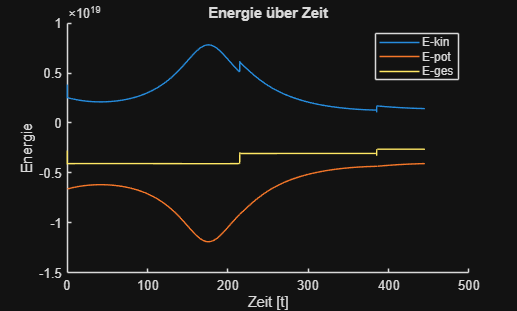

%Energien über energy_calc() berechnen, Positionen der Sonde werden
%übergeben
[kin_energy, pot_energy, sum_energy] = energy_calc(y);

%Plotten
figure;
hold on;
plot(t, kin_energy);
plot(t, pot_energy);
plot(t, sum_energy);
title("Energie über Zeit");
xlabel("Zeit [t]");
ylabel("Energie");
legend("E-kin", "E-pot", "E-ges");